# The Logistic Function

Note: this script reproduces the figure of the logistic function in Section 6.4 of **Statistics for Chemical Engineers**. Victor Z UW-Madison, 2019 visualize logistic function

clc; clear all; close all hidden;

## Logistic function for different parameters

span parameter

theta=[-1,0,1];

% span x space
x = linspace(-5,5);

for k=1:length(theta)
    theta(k)
    y=1./(1+exp(-theta(k)*x));
    figure(1)
    subplot(3,3,k)
    plot(x,y,'LineWidth',1.5,'Color','black');
    hold on
    grid on
    set(gca,'FontSize',14)
    xlabel('$x$','Interpreter','latex','FontSize', 14)
    ylabel('$m(x,\theta)$','Interpreter','latex','FontSize',14)
    axis([-5 5 0 1])
end

ans =          -1.00

ans =              0

ans =           1.00

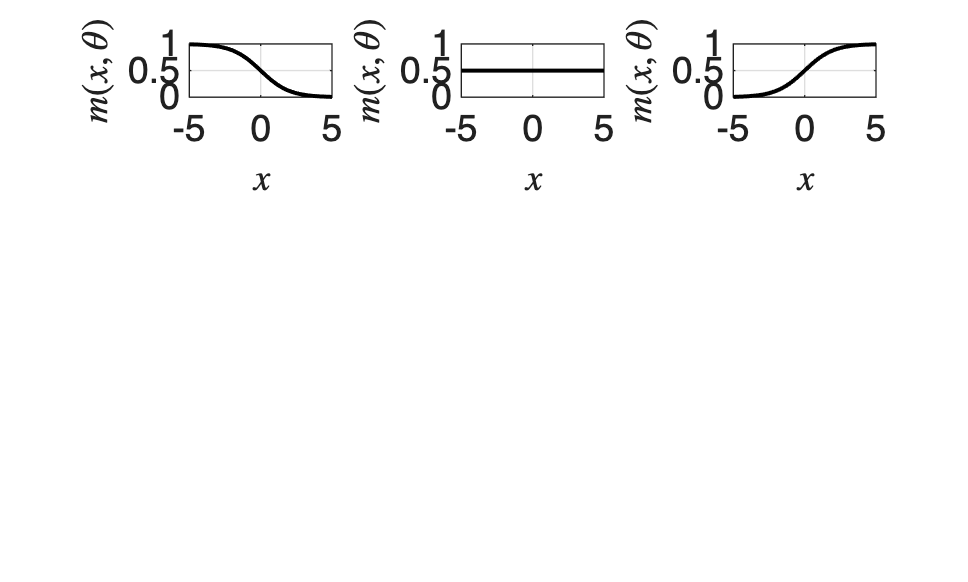

print -depsc ch6_logistic_function.eps

## Note

The logistic function maps any input to a probability between 0 and 1; its parameters shift and sharpen the transition.